# ゴール期待値からゴール数の確率分布を求める

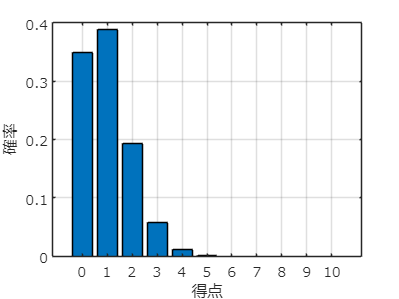

clear;
clc;
close all;

xGs=0.1*ones(10,1);
pGoals=1;

for n1=1:size(xGs,1)
    pGoals=conv(pGoals,[1-xGs(n1), xGs(n1)]);
end

figure
bar(0:size(xGs,1), pGoals);
set(gca,'fontname','メイリオ');grid on;
xlabel('得点');ylabel('確率');